# Task 3: Method Evaluation (Regression)

clear all;
close all;

% load raw dataset
regression_data = table2array(readtable('Dataset\Regression\Range-Queries-Aggregates.csv'));

% remove invalid data row (empty value)
nan_idx = find(isnan(regression_data(:, 8)));
regression_data(nan_idx, :) = [];

% shuffling of data
shuffled_data = regression_data(randperm(size(regression_data, 1)), :);

% take the first 20000 row of dataset
shuffled_data = shuffled_data(1: 20000, :);

% obtaining mean square error of all kernels
linear_kernel_error_result = linear_kernel_regression(shuffled_data);
polynomial_kernel_error_result = polynomial_kernel_regression(shuffled_data);
gaussian_kernel_error_result = gaussian_kernel_regression(shuffled_data);

% T-test for all combination of kernel models
ttest_gaussian_linear=ttest2(gaussian_kernel_error_result(:, 4),linear_kernel_error_result(:, 3), 'Vartype', 'unequal');

ttest_gaussian_linear = 1

ttest_gaussian_polynomial=ttest2(gaussian_kernel_error_result(:, 4),polynomial_kernel_error_result(:, 4), 'Vartype', 'unequal');

ttest_gaussian_polynomial = 1

ttest_polynomial_linear=ttest2(polynomial_kernel_error_result(:, 4),linear_kernel_error_result(:, 3), 'Vartype', 'unequal');

ttest_polynomial_linear = 1


% values for x-axis
x = linspace(0, 30, 1000)

x =          0    0.0300    0.0601    0.0901    0.1201    0.1502    0.1802    0.2102    0.2402    0.2703    0.3003    0.3303    0.3604    0.3904    0.4204    0.4505    0.4805    0.5105    0.5405    0.5706    0.6006    0.6306    0.6607    0.6907    0.7207    0.7508    0.7808    0.8108    0.8408    0.8709    0.9009    0.9309    0.9610    0.9910    1.0210    1.0511    1.0811    1.1111    1.1411    1.1712    1.2012    1.2312    1.2613    1.2913    1.3213    1.3514    1.3814    1.4114    1.4414    1.4715


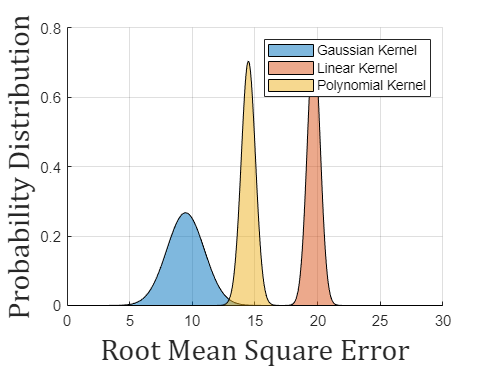


% calculation of normal probabilty distribution of all kernel models
d1 =  normpdf(x, mean(gaussian_kernel_error_result(:, 4)), std(gaussian_kernel_error_result(:, 4)));
d2 =  normpdf(x, mean(linear_kernel_error_result(:, 3)), std(linear_kernel_error_result(:, 3)));
d3 =  normpdf(x, mean(polynomial_kernel_error_result(:, 4)), std(polynomial_kernel_error_result(:, 4)));

% plotting of all normal probability distribution graph for comparison
figure;
hold on;
grid on;
area(x, d1);
alpha(0.5);
area(x, d2);
alpha(0.5);
area(x, d3);
alpha(0.5);
xlabel('Root Mean Square Error', FontName='Cambria', FontSize= 20);
ylabel('Probability Distribution', FontName='Cambria', FontSize= 20);
legend('Gaussian Kernel', 'Linear Kernel', 'Polynomial Kernel');

### Function to Generate Mean Square Errors of Various Hyperparameters in Gaussian Kernel

function gaussian_result = gaussian_kernel_regression(shuffled_data)
    % obtaining the number of data instances per split
    partition_size = size(shuffled_data, 1) / 10;
    
    gaussian_result  = [];
    
    % prepartion of 10 different combination data points
    for i = 1: 10
        % preparation of test data
        test_data = shuffled_data(int16((i - 1) * partition_size + 1: i * partition_size), :);
        % preparation of training data
        training_data = shuffled_data;
        training_data(int16((i - 1) * partition_size + 1: i * partition_size), :) = [];
        % normalization of test data
        test_X = normalize(test_data(:, 2: 7));
        test_Y = test_data(:, 8);
        % normalization of training data
        training_X = normalize(training_data(:, 2: 7));
        training_Y = training_data(:, 8);
        % generation of the best hyperparameters
        [box_constraint, kernelscale, epsilon] = innerCrossValidation_gaussian_kernel_regression(training_X, training_Y);   
        % fitting the Gaussian kernel model with the best combination of hyperparameters
        Mdl = fitrsvm(training_X, training_Y, "BoxConstraint", box_constraint, "KernelScale", kernelscale, "Epsilon", epsilon, "KernelFunction", 'gaussian');
        % prediction of y made by the Gaussian model
        pre_y = predict(Mdl, test_X);
        % calculation of the mean square error made by the model
        RMSE = sqrt(mean((test_Y - pre_y).^2));
        % concatination of hyperparameters value with the mean square error generated from each iteration
        gaussian_result = [gaussian_result ; box_constraint kernelscale epsilon RMSE];
    end

end

### Function to Generate Mean Square Errors of Various Hyperparameters in Polynomial Kernel

function polynomial_result = polynomial_kernel_regression(shuffled_data)
    % obtaining the number of data instances per split
    partition_size = size(shuffled_data, 1) / 10;
    
    polynomial_result = [];
    
    % prepartion of 10 different combination data points
    for i = 1: 10
        % preparation of test data
        test_data = shuffled_data(int16((i - 1) * partition_size + 1: i * partition_size), :);
        % preparation of training data
        training_data = shuffled_data;
        training_data(int16((i - 1) * partition_size + 1: i * partition_size), :) = [];
        % normalization of test data
        test_X = normalize(test_data(:, 2: 7));
        test_Y = test_data(:, 8);
        % normalization of training data
        training_X = normalize(training_data(:, 2: 7));
        training_Y = training_data(:, 8);
        % generation of the best hyperparameters
        [box_constraint, polynomial_order, epsilon] = innerCrossValidation_polynomial_kernel_regression(training_X, training_Y);   
        % fitting the Polynomial kernel model with the best combination of hyperparameters
        Mdl = fitrsvm(training_X, training_Y, "BoxConstraint", box_constraint, 'PolynomialOrder', polynomial_order, "Epsilon", epsilon, "KernelFunction", 'polynomial');
        % prediction of y made by the Polynomial model
        pre_y = predict(Mdl, test_X);
        % calculation of the mean square error made by the model
        RMSE = sqrt(mean((test_Y - pre_y).^2));
        % concatination of hyperparameters value with the mean square error generated from each iteration
        polynomial_result = [polynomial_result; box_constraint polynomial_order epsilon RMSE];
    end

end

### Function to Generate Mean Square Errors of Various Hyperparameters in Linear Kernel

function linear_result = linear_kernel_regression(shuffled_data)
    % obtaining the number of data instances per split
    partition_size = size(shuffled_data, 1) / 10;
    
    linear_result = [];
    
    for i = 1:10
        % preparation of test data
        test_data = shuffled_data(int16((i - 1) * partition_size + 1: i * partition_size), :);
        % preparation of training data
        training_data = shuffled_data;
        training_data(int16((i - 1) * partition_size + 1: i * partition_size), :) = [];
        % normalization of test data
        test_X = normalize(test_data(:, 2: 7));
        test_Y = test_data(:, 8);
        % normalization of training data
        training_X = normalize(training_data(:, 2: 7));
        training_Y = training_data(:, 8);
        % generation of the best hyperparameters
        [box_constraint, epsilon] = innerCrossValidation_linear_kernel_regression(training_X, training_Y);   
        % fitting the Linear kernel model with the best combination of hyperparameters
        Mdl = fitrsvm(training_X, training_Y, "BoxConstraint", box_constraint, "Epsilon", epsilon, "KernelFunction", 'linear');
        % prediction of y made by the Linear model
        pre_y = predict(Mdl, test_X);
        % calculation of the mean square error made by the model
        RMSE = sqrt(mean((test_Y - pre_y).^2));
        % concatination of hyperparameters value with the mean square error generated from each iteration
        linear_result = [linear_result ; box_constraint epsilon RMSE];
    end
end

### Inner Cross-validation Routine for Gaussian RBF Kernel Model (Regression)

function [bc, ks, ep] = innerCrossValidation_gaussian_kernel_regression(training_X,training_Y)
    
    % split dataset into training and validation set
    Inner_training_X = training_X(1: 0.5* height(training_X), :);
    Inner_validation_X = training_X(0.5* height(training_X)+ 1: end, :);

    Inner_training_Y = training_Y(1: 0.5* height(training_Y), :);
    Inner_validation_Y = training_Y(0.5* height(training_Y)+ 1: end, :);

    % setting the maximum number of generation and offspring per generation
    max_generation = 10;
    no_of_offspring = 10;

    % setting the value of BoxConstraint, KernelScale, Epsilon
    Box_constraint = randsample(logspace(-3, 3), 10).';
    Kernel_scale = randsample(logspace(-3, 3), 10).';
    Epsilon = ((randsample(logspace(-3, 2), 10))*(iqr(Inner_validation_Y)/ 1.34)).';
    % concatenation of Box_constraint, Kernel_scale, Epsilon and a column of 10 zeros that represents the error rate
    hyperparameters = [Box_constraint Kernel_scale Epsilon zeros(10, 1)];
    best_among_generation = [];

    % main loop for evolutionary algorithm for hyperparameter tuning
    for i = 1: max_generation
        % loop for offspring generation
        for j = 1: no_of_offspring
            % training of gaussian model, conducting prediction based on Inner_validation_X, returning the error rate of the model
            [~, error] = train_gaussian_model(Inner_training_X, Inner_training_Y, Inner_validation_X, Inner_validation_Y, hyperparameters(j, 1), hyperparameters(j, 2), hyperparameters(j, 3));
            % swapping of training and validation dataset in inner cross-validation
            [Inner_training_X, Inner_validation_X] = swap(Inner_training_X, Inner_validation_X);
            [Inner_training_Y, Inner_validation_Y] = swap(Inner_training_Y, Inner_validation_Y);
            % training of gaussian model using the swapped dataset, returning a new error rate for comparison
            [~, temp_error] = train_gaussian_model(Inner_training_X, Inner_training_Y, Inner_validation_X, Inner_validation_Y, hyperparameters(j, 1), hyperparameters(j, 2), hyperparameters(j, 3));
            % calculation of average error rate
            hyperparameters(j, 4) = (error + temp_error)/2;
        end
        % sorting the hyperparameters based on the error rate
        [~, idx] = sort(hyperparameters(:, 4));
        % obtaining the index of the sorted hyperparameters
        sorted_hyperparameters = hyperparameters(idx, :); 
        % retrieving parent 
        hyperparameters(1) = sorted_hyperparameters(1);
        % obtaining random distribution of each column of hyperparameters (Box_constraint, Kernel_space, Epsilon)
        for k= 1: 3
           hyperparameters(2: 10, k)=abs(normrnd(sorted_hyperparameters(1, k), 1,[1, 9])); 
        end
        % collection of best hyperparameters within each generation
        best_among_generation = [best_among_generation;sorted_hyperparameters(1, :)];
    end
    % sorting the best hyperparameters in ascending order based on error rate
    [~, idx] = sort(best_among_generation(:, 4));
    sorted_best_among_hyperparameters = best_among_generation(idx, :); 
    bc = sorted_best_among_hyperparameters(1, 1);
    ks = sorted_best_among_hyperparameters(1, 2);
    ep = sorted_best_among_hyperparameters(1, 3);
    
end

### Function to Perform Training and Prediction with Gaussian RBF Kernel Model

function [Regression_Mdl, error] = train_gaussian_model(training_data_x, training_data_Y, validating_data_x, validating_data_Y, Box_constraint, Kernel_scale, Epsilon)
    % training of gaussian model (Regression)    
    Regression_Mdl = fitrsvm(training_data_x, training_data_Y, 'KernelFunction', "rbf", 'BoxConstraint', Box_constraint, 'KernelScale', Kernel_scale, 'Epsilon', Epsilon);
    % conducting prediction
    prediction_y = predict(Regression_Mdl, validating_data_x);
    % calculation of mean square error rate
    error = sqrt(mean((validating_data_Y - prediction_y ).^2));
end

### Inner Cross-validation Routine for Linear Kernel Model (Regression)

function [bc, ep] = innerCrossValidation_linear_kernel_regression(training_X, training_Y)

    % split dataset into training and validation set
    Inner_training_X = training_X(1: 0.5* height(training_X),:);
    Inner_validation_X = training_X(0.5* height(training_X)+ 1: end, :);

    Inner_training_Y = training_Y(1: 0.5* height(training_Y),:);
    Inner_validation_Y = training_Y(0.5* height(training_Y)+ 1: end, :);

    % setting the maximum number of generation and offspring per generation
    max_generation = 10;
    no_of_offspring = 10;
    
    % setting the value of BoxConstraint, Epsilon
    Box_constraint = randsample(logspace(-3, 3), 10).';
    Epsilon = ((randsample(logspace(-3, 2), 10))* (iqr(Inner_validation_Y)/ 1.34)).';
    % concatenation of Box_constraint, Epsilon and a column of 10 zeros that represents the error rate
    hyperparameters = [Box_constraint Epsilon zeros(10, 1)];
    best_among_generation = [];

    for i = 1: max_generation
        for j = 1: no_of_offspring
            % training of linear model, conducting prediction based on Inner_validation_X, returning the error rate of the model
            [~, error] = train_linear_model(Inner_training_X, Inner_training_Y, Inner_validation_X, Inner_validation_Y, hyperparameters(j, 1), hyperparameters(j, 2));
            % swapping of training and validation dataset in inner cross-validation
            [Inner_training_X, Inner_validation_X] = swap(Inner_training_X, Inner_validation_X);
            [Inner_training_Y, Inner_validation_Y] = swap(Inner_training_Y, Inner_validation_Y);
            % training of linear model using the swapped dataset, returning a new error rate for comparison
            [~, temp_error] = train_linear_model(Inner_training_X, Inner_training_Y, Inner_validation_X, Inner_validation_Y, hyperparameters(j, 1), hyperparameters(j, 2));
            % calculation of average error rate
            hyperparameters(j, 3) = (error+ temp_error)/ 2;
        end
        % sorting the hyperparameters based on the error rate
        [~, idx] = sort(hyperparameters(:, 3));
        % obtaining the index of the sorted hyperparameters
        sorted_hyperparameters = hyperparameters(idx, :);
        % retrieving parent
        hyperparameters(1, 1: 3) = sorted_hyperparameters(1, 1: 3);
        % obtaining random distribution of each column of hyperparameters (Box_constraint, Epsilon)
        for k= 1: 2
           hyperparameters(2: 10, k)=abs(normrnd(sorted_hyperparameters(1, k),1, [1, 9])); 
        end
        % collection of best hyperparameters within each generation
        best_among_generation = [best_among_generation;sorted_hyperparameters(1, :)];
    end
    % sorting the best hyperparameters in ascending order based on error rate
    [~, idx] = sort(best_among_generation(:, 3));
    sorted_best_among_hyperparameters = best_among_generation(idx, :); 
    bc = sorted_best_among_hyperparameters(1, 1);
    ep = sorted_best_among_hyperparameters(1, 2);
    
end

### Function to Perform Training and Prediction with Linear Kernel Model

function [Regression_Mdl, error] = train_linear_model(training_data_x, training_data_Y, validating_data_x, validating_data_Y, Box_constraint, Epsilon)
    % training of linear model (Regression)    
    Regression_Mdl = fitrsvm(training_data_x, training_data_Y, 'KernelFunction', "linear", 'BoxConstraint', Box_constraint, 'Epsilon', Epsilon);
    % conducting prediction
    prediction_y = predict(Regression_Mdl, validating_data_x);
    % calculation of mean square error rate
    error = sqrt(mean((validating_data_Y - prediction_y ).^2));
end

### Inner Cross-validation Routine for Polynomial Kernel Model (Regression)

function [bc, po, ep] = innerCrossValidation_polynomial_kernel_regression(training_X, training_Y)
    % split dataset into training and validation set
    Inner_training_X = training_X(1: 0.5* height(training_X),:);
    Inner_validation_X = training_X(0.5* height(training_X)+ 1: end, :);

    Inner_training_Y = training_Y(1: 0.5* height(training_Y), :);
    Inner_validation_Y = training_Y(0.5* height(training_Y)+ 1: end, :);
    
    % setting the maximum number of generation and offspring per generation
    max_generation = 10;
    no_of_offspring = 10;
    
    % setting the value of BoxConstraint, PolynomialOrder, Epsilon
    Box_constraint = randsample(logspace(-3, 3), 10).';
    Polynomial_order = randi([2, 4], 10, 1);
    Epsilon = ((randsample(logspace(-3, 2), 10))*(iqr(Inner_validation_Y)/ 1.34)).';
    % concatenation of Box_constraint, PolynomialOrder, Epsilon and a column of 10 zeros that represents the error rate
    hyperparameters = [Box_constraint Polynomial_order Epsilon zeros(10, 1)];
    best_among_generation = [];

    for i = 1: max_generation        
        for j = 1: no_of_offspring
            % training of polynomial model, conducting prediction based on Inner_validation_X, returning the error rate of the model
            [~, error] = train_polynomial_model(Inner_training_X, Inner_training_Y, Inner_validation_X, Inner_validation_Y, hyperparameters(j, 1), hyperparameters(j, 2), hyperparameters(j, 3));
            % swapping of training and validation dataset in inner cross-validation
            [Inner_training_X, Inner_validation_X] = swap(Inner_training_X, Inner_validation_X);
            [Inner_training_Y, Inner_validation_Y] = swap(Inner_training_Y, Inner_validation_Y);
            % training of polynomial model using the swapped dataset, returning a new error rate for comparison
            [~, temp_error] = train_polynomial_model(Inner_training_X, Inner_training_Y, Inner_validation_X, Inner_validation_Y, hyperparameters(j, 1), hyperparameters(j, 2), hyperparameters(j, 3));
            % calculation of average error rate
            hyperparameters(j, 4) = (error+ temp_error)/ 2;
        end
        % sorting the hyperparameters based on the error rate
        [~, idx] = sort(hyperparameters(:, 4));
        % obtaining the index of the sorted hyperparameters
        sorted_hyperparameters = hyperparameters(idx, :); 
        % obtaining random distribution of each column of hyperparameters (Box_constraint, Polynomial_order)
        hyperparameters(1: 10, 1)=abs(normrnd(sorted_hyperparameters(1, 1), 1, [1, 10])); 
        hyperparameters(1: 10, 2)=round(abs(normrnd(sorted_hyperparameters(1, 2),1, [1, 10])));
        temp = hyperparameters(1: 10, 2);
        % assigning Polynomial_order of invalid value with the best value among the generation
        temp(temp == 0)=sorted_hyperparameters(1, 2);
        temp(temp >= 5)=sorted_hyperparameters(1, 2);
        temp(temp == 1)=sorted_hyperparameters(1, 2);
        hyperparameters(1: 10, 2)= temp;
        hyperparameters(1: 10, 3)= abs(normrnd(sorted_hyperparameters(1, 3), 3, [1, 10])); 
        % collection of best hyperparameters within each generation
        best_among_generation = [best_among_generation; sorted_hyperparameters(1, :)];
    end
    % sorting the best hyperparameters in ascending order based on error rate
    [~, idx] = sort(best_among_generation(:, 4));
    sorted_best_among_hyperparameters = best_among_generation(idx, :); 
    bc = sorted_best_among_hyperparameters(1, 1);
    po = sorted_best_among_hyperparameters(1, 2);
    ep = sorted_best_among_hyperparameters(1, 3);
    
end

### Function to Perform Training and Prediction with Polynomial Kernel Model

function [Regression_Mdl, error] = train_polynomial_model(training_data_x, training_data_Y, validating_data_x, validating_data_Y, Box_constraint, Polynomial_Order, Epsilon)
    % training of polynomial model (Regression)    
    Regression_Mdl = fitrsvm(training_data_x, training_data_Y, 'KernelFunction', 'polynomial', 'BoxConstraint', Box_constraint, 'PolynomialOrder', Polynomial_Order, 'Epsilon', Epsilon);
    % conducting prediction
    prediction_y = predict(Regression_Mdl, validating_data_x);
    % calculation of mean square error rate
    error = sqrt(mean((validating_data_Y - prediction_y ).^2));
end

### Function to Swap Input Arguments

function [b, a] = swap(a, b)
% performing a swap between input arguments
end